# Rocket Model

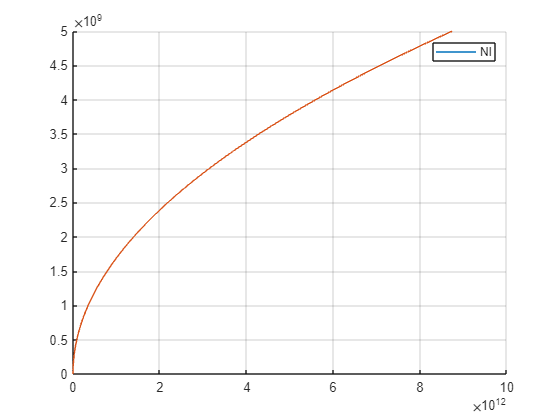

clear

tspan = linspace(0,100,1000);
options = odeset('RelTol',1e-5);

phi = deg2rad(-2);
Ft = 1000000;

x0 = [0 0 0 0 deg2rad(0) 0];
[t,y] = ode23t(@(t,X) nonlinear(t,X,phi,Ft),tspan,x0,options);

[t1,y1] = ode23t(@(t1,X1) linear(t1,X1,phi,Ft),tspan,x0);


figure
hold on
plot (y(:,1),y(:,3));
plot (y1(:,1),y1(:,3));
hold off
grid on;
legend(["Nl"])

function X_dot  = nonlinear(~,X, phi, Ft)

g = 9.81;
l = 100;
M = 1000;

X_dot = [X(2); (Ft*sin(phi)*cos(X(5)) + sin(X(5))*Ft*cos(phi))/M; X(4); (Ft*cos(phi)*cos(X(5)) - Ft*sin(phi)*sin(X(5)))/M - g; X(6); -6*(Ft*sin(phi)/(M*l))];

end

% function X_dot  = linear(~,X, phi, Ft)
% 
% g = 9.81;
% l = 100;
% M = 1000;
% 
% Ft0 = Ft;
% theta0 = X(5);
% phi0 = phi;
% 
% A = [0 1 0 0 0 0; 0 0 0 0 Ft0/M 0; 0 0 0 1 0 0; 0 0 0 0 -Ft0*phi0/M 0; 0 0 0 0 0 1; 0 0 0 0 0 0];
% B = [0 0; (theta0+phi0)/M Ft0/M; 0 0; (1-(phi0*theta0))/M -(Ft0*theta0/M); 0 0; -(6/M*l)*phi0 -6*(Ft0/M*l)];
% 
% X_dot = A*X + B*[Ft; phi];
% 
% end

function X_dot  = linear(~,X, phi, Ft)

g = 9.81;
l = 100;
M = 1000;

%X_dot = [X(2); (Ft*phi + X(5)*Ft)/M; X(4); (Ft - Ft*X(5)*phi)/M - g; X(6); -6*(Ft*phi/(M*l))];

A = [0 1 0 0 0 0; 0 0 0 0 -Ft*cos(phi) 0; 0 0 0 1 0 0; 0 0 0 0 0 0; 0 0 0 0 0 1; 0 0 0 0 0 0];
B = [0 0; 1 0; 0 0; 0 1; 0 0; 6/(M*l) 0];

X_dot = A*X + B*[Ft*sin(phi); Ft*cos(phi) - g];


end